# **PORTFOLIO THFORY (STA4028Z)**

# Data Wrangling and Optimization in MATLAB

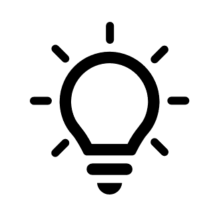 Where do I find MATLAB? [Here](https://www.mathworks.com/academia/tah-portal/university-of-cape-town-31484474.html)!

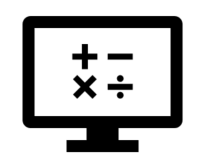 Do I have to have MATLAB installed on my computer right now? No, you can use  [MALAB Online](https://matlab.mathworks.com/)!

**Recommended Lecture Readings:** 

- Carmona, R., (2014) Statistical Analysis of Financial Data in R, Springer

**Recommended Course Reading:** 

- Elton, E., Gruber, M., Brown, S., and Goetzmann, W., (2014), Modern Portfolio Theory and Investment Analysis, 9-th edition, Wiley [Chapters 13, 17, 26, 28] 

- Lee, W., (2000)Theory and Methodology of Tactical Asset Allocation [Chapter 2, 3, 7] 

- Prigent, P-L., (2007), Portfolio Optimization and Performance analysis. Chapman & Hall [Chapter 1, ...] 

- Ross, S., (2005), Neoclassical Finance, Princeton Press [Chapter 1]

#### Markdown

### Rules of Engagement

- You are strongly encouraged to **workshop and discuss assignment outputs**, graphs, tables and algorithms in order to refine your thinking about assignment solutions.

- **There is to be no code sharing**. Duplicate code will be treated as plagiarism, and as such, intellectual property theft. 

-  All MATLAB code is to be included in the appendix of your assignment submission marked up in the appropriate LaTeX environment. Where appropriate referenced by code pattern in the body of the assignment.

- All equations used should be presented and discussed using the correct TeX markup. 

- MATLAB code executed within the document is to be suppressed where appropriate. The output is what is of interest in the body of the assignment text.

#### Script file description

Load the Tactical Asset Allocation data from EXCEL 

-  ICB Industrial Level Indices 

-  ALBI (All Bond Index (ALBI) Total Return Index (TRI) Data) 

-  Money Market Data: JIBAR and STEFI TRI 

-  Various Indices: JSE Growth, JSE Value, JSE ALSI, JSE SRI 

 Situation: Load data from *.csv file and convert into timeSeries 

To open Excel spreadsheet: Navigate to the folder in the current folder, right click on spreadsheet and choose "Open Outside MATLAB"

#### Clear environment and remove all plots

clc % clears the command window
close all %removes all figures
clear % clears the workspace

####  Paths

Use your user path and folders to specify the correct path using absolute paths

% use your default user path to create the filename and path
fileName = "C:\Users\User\OneDrive - University of Cape Town\Notes Honours 2025\Portfolio Theory\Portfolio_Theory_A1\Data\PT-DATA-ALBI-JIBAR-JSEIND-Daily-1994-2017.xlsx"

fileName = "C:\Users\User\OneDrive - University of Cape Town\Notes Honours 2025\Portfolio Theory\Portfolio_Theory_A1\Data\PT-DATA-ALBI-JIBAR-JSEIND-Daily-1994-2017.xlsx"

%fileName = fullfile(userpath,'STA4028Z/Data',fileName)

### Loading the data from Excel spreadsheets 

Load the dataset by sheet using [readtimetable](https://www.mathworks.com/help/matlab/ref/readtimetable.html). MATLAB has many functions to read in data in the format you would like to use it in. See [`readtable`](https://www.mathworks.com/help/matlab/ref/readtable.html)`,` [`readmatrix`](https://www.mathworks.com/help/matlab/ref/readmatrix.html)`, `[`readvars`](https://www.mathworks.com/help/matlab/ref/readvars.html)`, `[`readcell`](https://www.mathworks.com/help/matlab/ref/readcell.html)`.`

Timetable is a type of table that associates a time with each row. Like table, the timetable data type can store column-oriented data variables that have the same number of rows. All table functions work with timetables. In addition, timetables provide time-specific functions to align, combine, and perform calculations with one or more timetables. For more information, see [Create Timetables](https://www.mathworks.com/help/matlab/matlab_prog/create-timetables.html) or watch [Managing Time-Stamped Tabular Data with Timetables](https://www.mathworks.com/videos/managing-time-stamped-tabular-data-with-timetable-120888.html).

The loaded Excel sheets will be saved in a [cell array](https://www.mathworks.com/help/matlab/cell-arrays.html). A cell array is a data type with indexed data containers called cells. Each cell can contain any type of data. Cell arrays commonly contain pieces of text, combinations of text and numbers from spreadsheets or text files, or numeric arrays of different sizes.

excelSheetNames = sheetnames(fileName);
% Preallocate cell array before looping
data{numel(excelSheetNames)} = [];
% Load the dataset by sheet
for sheet = 1:numel(excelSheetNames)
data{sheet} = readtimetable(fileName,'Sheet',excelSheetNames{sheet},VariableNamingRule='preserve', VariableNamesRange ='A1', VariableDescriptionsRange = 'A2',Range='A5');
end

#### Keep only the specified list of Tickers

Find Tickers in the column names and keep the TRI only of sheets JSE ICB 0500 Indices and JSE Various Indices.

[strncmp](https://www.mathworks.com/help/matlab/ref/strncmp.html) is one of the text comparison functions that can be used. Read more [here](https://www.mathworks.com/help/matlab/matlab_prog/string-comparisons.html).

variableTickers = string("J5" + (10 : 10 : 90));
entities = {'RATESTEFI', 'ALBI', 'J203', 'J500', variableTickers{:}};

for i = 1:numel(data)
    % 1. Keep TRI only in sheets 3 and 4
    if i == 3
       allVarTable = data{i}; 
       TRITable = allVarTable(:,(3:3:27));
       data{i} = TRITable;
    elseif i == 4
       allVarTable = data{i};
       allVarTable = removevars(allVarTable,["SOURCE68779","Var2"]);
       TRITable = allVarTable(:,(4:4:19));
       data{i} = TRITable;
    end
    % 2. Find Tickers in column names,
        % get the table properties
        opts = data{i}.Properties;
        % Preallocate array for matching
        variableMatch = zeros(size(opts.VariableNames));   
        % Do a string comparison to find tickers
        if i == 2 %Match 8 letters for STEFI to prevent unwanted variables
            for k = 1:numel(entities)
                variableMatch(strncmp(opts.VariableNames,entities{k},8)) = k;
            end
        else
            for k = 1:numel(entities)
                variableMatch(strncmp(opts.VariableNames,entities{k},4)) = k;
            end
        end
        % Index for unwanted tickers
        idx = find(variableMatch==0);
        %Remove unwanted tickers from the data
        tickersToBeRemoved = opts.VariableNames(idx);
        data{i} = removevars(data{i}, tickersToBeRemoved);
        % clean up the remaining column names 
        hasColon = contains(data{i}.Properties.VariableNames, ':');     
        data{i}.Properties.VariableNames(hasColon) = extractBefore(data{i}.Properties.VariableNames(hasColon),':');
end

#### Clean and convert into a single timetable

Combine all four tables into one using synchronize. 

The synchronize function collects the variables from all input timetables, synchronizes them to a common time vector, and returns the result as a single timetable. The effect is similar to a horizontal concatenation, though the input timetables can have different row times. When the synchronize function synchronizes timetable variables to different times, it also resamples or aggregates the data in the variables using a method that you specify.

allDataTable = synchronize(data{1},data{2},data{3},data{4});
%Rename variables
allDataTable = renamevars(allDataTable,{'RATESTEFI','J203'}, {'STEFI','ALSI'});

#### Down-sample (by decimation) and Visualise 

Convert from Daily Sampled Data to Monthly Sampled Data. 

% Decimate the daily data to monthly data
allDataTable = convert2monthly(allDataTable);

Remove dates in the timetable where data is not recorded, i.e holidays,weekends once you are at the required sampling frequency. First, visualise where there is missing data (e.g. a NaN).

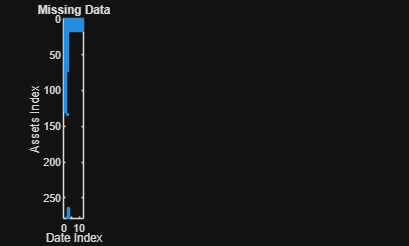

figure;
subplot(1,6,1);
spy(isnan(table2array(allDataTable)));
ylabel("Assets Index")
xlabel("Date Index")
title("Missing Data")

% [left bottom width height]
%ax.OuterPosition = [ax.OuterPosition(1:3) ax.OuterPosition(4)];

#### Missing Data

The recording of ALBI and STEFI indices starts a lot later than the other indices and removing all missing data would erase any data recorded prior. There are also assets which delisted or were discontinued and hence they no-longer have recorded data at the end of the dataset. We could fill the missing data with the last measure data set using the prices. There returns would then become zero moving forward.    

% we are going to use zero-order hold (the missing price is the last price)
allDataTableFilled = fillmissing(allDataTable,'previous');
subplot(1,6,2);
spy(isnan(table2array(allDataTableFilled)));

Here we want to find that data set where all the asset are populated sequentially. Having a single missing data point is okay but more than two in a sequence is a problem. We can find a variable with the least nans and use it as a proxy to remove the missing data from the beginning of the dataset up until that point.

[minNans,idx] = min(sum(isnan(allDataTable{:,:}),1));
rmmissingProxy =  allDataTable.Properties.VariableNames{idx};
allDataTable = rmmissing(allDataTable,"DataVariables",rmmissingProxy);
subplot(1,6,3);
spy(isnan(table2array(allDataTable)));

The problem is that we see that there is still missing data in the first 3 asset, and for the 3rd asset at the end too. This asset is J500, this is the old Oil&Gas Index, the index was discontinued. Here we will remove this from our dataset.

idxJ500=contains(allDataTable.Properties.VariableNames,'J500');
idx = 1:width(allDataTable);
allDataTable = allDataTable(:,idx(~idxJ500))

allDataTable = 261×11 timetable
       Time        ALBI    STEFI     J510      J520      J530      J540      J550      J560      J580      J590      ALSI 
    ___________    ____    _____    ______    ______    ______    ______    ______    ______    ______    ______    ______

    30-Jun-1995    NaN      NaN     357.54    493.64    232.92    512.36    992.26    526.97    476.25    695.15     366.6
    31-Jul-1995    NaN      NaN     360.38    510.11     235.1    527.57     995.5    530.97    470.56     718.1    369.87
    31-Aug-1995 

subplot(1,6,4);
spy(isnan(table2array(allDataTable)));

We can try remove all the missing data in the early part of the dataset. 

Note:  Take care not to include data prior to this. 

[countNans,idx] = max(sum(isnan(allDataTable{:,:}),1));
rmmissingProxy =  allDataTable.Properties.VariableNames{idx};
allDataTable0 = rmmissing(allDataTable,"DataVariables",rmmissingProxy);
spy(isnan(table2array(allDataTable0)));

Notice that we now had non-uniformly sampled data:

allDataTable0(1:3,:)

ans = 3×11 timetable
       Time         ALBI     STEFI      J510      J520      J530      J540      J550      J560      J580      J590      ALSI 
    ___________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    31-Aug-2003    173.72    137.02    833.01    1027.2     670.2    839.04    1241.7    1366.5    987.19    682.94    866.96
    30-Nov-2004    205.71    151.87    1188.4    1852.5    913.29    1435.4      2402    2984.3    1649.3    901.26    1219.6
    31-Dec-2004

We can check for uniformity in the data ranges to show that this is only in the first row of data

find(diff(datenum(allDataTable0.Time))>31)

ans = 1

We want to remove all the data upto the maximum NaN count and we will do this by reference

idx = isnan(allDataTable{:,:});
allDataTable = allDataTable(max(find(idx,max(max(cumsum(idx)))))+1:end,:);
allDataTable(1:3,:)

ans = 3×11 timetable
       Time         ALBI     STEFI      J510      J520      J530      J540      J550      J560      J580      J590      ALSI 
    ___________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    30-Nov-2004    205.71    151.87    1188.4    1852.5    913.29    1435.4      2402    2984.3    1649.3    901.26    1219.6
    31-Dec-2004       212    152.81      1237    1938.5    968.15    1427.9    2549.9    3103.1    1731.7    968.32    1237.2
    31-Jan-2005

find(diff(datenum(allDataTable.Time))>31)


ans =

  0×1 empty double column vector



subplot(1,6,5);
spy(isnan(table2array(allDataTable)));

There is still sequential missing data at the end of the data set. We should remove this too.

countNans = max(max(cumsum(isnan(allDataTable{:,:}))));
allDataTable = allDataTable(1:end-countNans+1,:);

We will then fill in the single missing STEFI missing data point.

allDataTableFilled = fillmissing(allDataTable,'previous')

allDataTableFilled = 146×11 timetable
       Time         ALBI     STEFI      J510      J520      J530      J540      J550      J560      J580      J590      ALSI 
    ___________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    30-Nov-2004    205.71    151.87    1188.4    1852.5    913.29    1435.4      2402    2984.3    1649.3    901.26    1219.6
    31-Dec-2004       212    152.81      1237    1938.5    968.15    1427.9    2549.9    3103.1    1731.7    968.32    1237.2
    31-

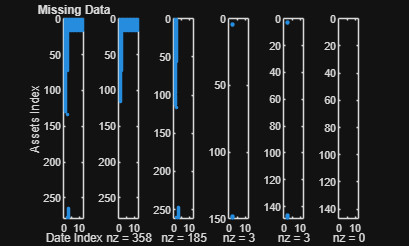

subplot(1,6,6);
spy(isnan(table2array(allDataTableFilled)));

find(diff(datenum(allDataTable.Time))>31)


ans =

  0×1 empty double column vector



We are keeping the data with this single missing point because this represent a case when measurements were not made but the index exists. This is different from the situations where the indices did not exist or were discontinued. 

#### Save your pre-processed data

The workspace is not maintained across sessions of MATLAB. When you quit MATLAB, the workspace clears. However, you can save any or all the variables in the current workspace to a MAT-file (`.mat`). You can then reuse the workspace variables later during the current MATLAB session or during another session by loading the saved MAT-file.

There are several ways to save workspace variables interactively:

- To save all workspace variables to a MAT-file, on the **Home** tab, in the **Variable** section, click **Save Workspace**.

- To save a subset of your workspace variables to a MAT-file, select the variables in the Workspace browser, right-click, and then select **Save As**. You also can drag the selected variables from the Workspace browser to the Current Folder browser.

- To save variables to a MATLAB script, click the **Save Workspace** button or select the **Save As** option, and in the **Save As** window, set the **Save as type** option to **MATLAB Script**. Variables that cannot be saved to a script are saved to a MAT-file with the same name as that of the script.

You also can save workspace variables programmatically using the [`save`](https://www.mathworks.com/help/matlab/ref/save.html) function. 

save("PortfolioTheory.mat",'allDataTableFilled')

Read more about saving options [here](https://www.mathworks.com/help/matlab/ref/save.html).

#### Visualisation

We can now plot the data (unfilled) as times series plots

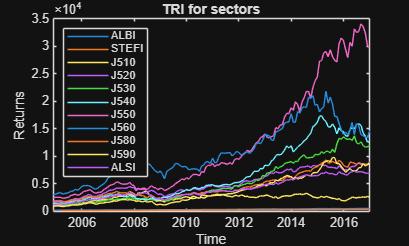


% Visualise the data on a single plot
%plot the timeseries
figure;
plot(allDataTable.Time,allDataTable{:,:})
ylabel("Returns")
xlabel("Time")
title("TRI for sectors")
%include the legend
legend(allDataTable.Properties.VariableNames,Location="northwest")

#### Compute returns

Compute returns Simple returns (rather than Continous returns)


$$R_t = \frac{P_t-P_{t-1}}{P_{t-1}} $$


% allDataReturnsTable = tick2ret(allDataTable,'Method','continuous');
allDataReturnsTable = tick2ret(allDataTable,'Method','Simple');

#### Visualise the Index and Return data

Plot two plots on the same figure 

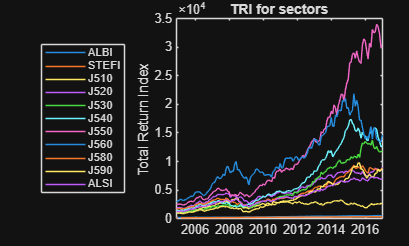

% Top plot
%plot the timeseries
plot(allDataTable.Time,allDataTable{:,:})
ylabel("Total Return Index")
title("TRI for sectors")
%include the legend
legend(allDataTable.Properties.VariableNames,Location="westoutside")
% Bottom plot
nexttile

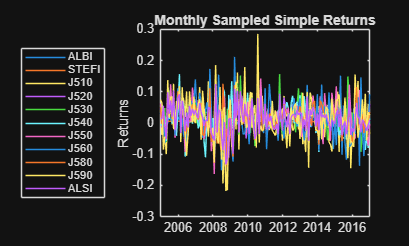

%plot the timeseries
plot(allDataReturnsTable.Time,allDataReturnsTable{:,:})
ylabel("Returns")
title("Monthly Sampled Simple Returns")
%include the legend
legend(allDataTable.Properties.VariableNames,Location="westoutside")

#### Manage Missing Data

Checking for missing data

any(isnan(allDataReturnsTable{:,:}))

ans = 1×11 logical array
   0   1   0   0   0   0   0   0   0   0   0


Compute the Arithmetic means without correcting for missing data (NAN)

portfolioMean = mean(allDataReturnsTable{:,:});  
portfolioStandardDev = std(allDataReturnsTable{:,:});

 If there are any missing data points exclude these from the estimation

portfolioMean = mean(allDataReturnsTable{:,:},'omitnan');
portfolioStdDev = std(allDataReturnsTable{:,:},1,'omitnan');
portfolioVariance = var(allDataReturnsTable{:,:},'omitnan');

We either remove all the rows with missing data or interpolate using zero-order hold (so pad with zero's for returns and with the previous price for prices

 allDataTable = fillmissing(allDataTable,'previous')

allDataTable = 146×11 timetable
       Time         ALBI     STEFI      J510      J520      J530      J540      J550      J560      J580      J590      ALSI 
    ___________    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______    ______

    30-Nov-2004    205.71    151.87    1188.4    1852.5    913.29    1435.4      2402    2984.3    1649.3    901.26    1219.6
    31-Dec-2004       212    152.81      1237    1938.5    968.15    1427.9    2549.9    3103.1    1731.7    968.32    1237.2
    31-Jan-20

 allDataReturnsTable = fillmissing(allDataReturnsTable,'constant',0)

allDataReturnsTable = 145×11 timetable
       Time           ALBI         STEFI         J510         J520          J530          J540          J550          J560          J580         J590          ALSI   
    ___________    __________    _________    __________    _________    __________    __________    __________    __________    __________    _________    __________

    31-Dec-2004      0.030602    0.0062095      0.040887     0.046385      0.060069    -0.0052389      0.061557      0.039798      0.049967     0.074407      0.014439
    31-Jan-2005  

### Load pre-processed data

#### Clear environment and remove all plots

clc % clears the command window
close all % removes all figures
clear % clears the workspace

Load previously prepared data

load('PortfolioTheory.mat')
% fill the missing data in the prices
allDataTable = allDataTableFilled;
% compute the simple returns
allDataReturnsTable = tick2ret(allDataTable,'Method','Simple')

allDataReturnsTable = 145×11 timetable
       Time           ALBI         STEFI         J510         J520          J530          J540          J550          J560          J580         J590          ALSI   
    ___________    __________    _________    __________    _________    __________    __________    __________    __________    __________    _________    __________

    31-Dec-2004      0.030602    0.0062095      0.040887     0.046385      0.060069    -0.0052389      0.061557      0.039798      0.049967     0.074407      0.014439
    31-Jan-2005  

% save the data
save("PortfolioTheory.mat",'allDataTable','allDataReturnsTable')

#### Different kinds of returns when considering compounding and means

We consider three different type of returns and there compunding. Here we use the ALBI index to demonstrate these. Prices at time t given by $P_t$ 

prc = allDataTable.ALBI;

The price relatives from time $t-1$ to $t$ are $x_t$ 


$$x_t = \frac{P_t}{P_{t-1}}$$
 

The returns $R_t$ (Simple) are then


$$R_t = \frac{P_t- P_{t-1}}{P_{t-1}} = x_t-1$$


The continous returns are $\mu_t$ (Continous)


$$\mu_t = \ln(P_r)-\ln(P_{t-1}) \iff P_t = e^{ \mu_t} P_{t-1} \iff x_t = e^{\mu_t}
$$


This is mathematically useful because it implies that: $P_t = P_0 e^{\mu_t t}$ given an initial price $P_0$.

It is computational convenient because returns can be efficientily computed over vectors

mut = diff(log(prc))

mut =     0.0301
    0.0144
    0.0197
   -0.0374
    0.0202
   -0.0010
    0.0265
    0.0096
    0.0006
    0.0008
    0.0063
    0.0234
    0.0195
    0.0096
    0.0077


The arithmetic average of this gives the mean continous returns: $\bar \mu = \frac{1}{n} \sum_{t=1}^n \mu_t$

mu =mean(mut)

mu = 0.0066

If the prices are log-normally distributed then the continous-returns will be normally distributed (they aren't on real world historic data).

Geometric returns are geometrically compounding over discrete time-intervals for times $t=0,1,2,\ldots,t,\ldots,n$ where there are $n+1$ prices and $n$ returns:


$$(R_1+1)(R_2+1) \ldots (R_t+1) \ldots (R_{n}+1) = \frac{P_1}{P_{0}}  \frac{P_2}{P_{1}}  \ldots \frac{P_t}{P_{t-1}}   \ldots \frac{P_n}{P_{n-1}} = \frac{P_n}{P_0}  
  $$


R = (prc(2:end)./prc(1:end-1))-1

R =     0.0306
    0.0145
    0.0199
   -0.0367
    0.0204
   -0.0010
    0.0269
    0.0096
    0.0006
    0.0008
    0.0063
    0.0237
    0.0197
    0.0096
    0.0078


The mean geometric returns are: $\mu_G =  \left( {\prod_{t=1}^n x_t} \right)^\frac{1}{n} -1= \left( {\prod_{t=1}^n (R_t+1)} \right)^\frac{1}{n} -1$ 

muG = exp(mean(log(R+1)))-1

muG = 0.0066

The mean arithmetic returns are: $\mu_A = \frac{1}{n} \sum_{t=1}^n R_t$

muA = mean(R)

muA = 0.0068

These are not the same. 

Note that because $\mu = \ln(\mu_G+1)$over the entire period we have

prc(1) * exp((length(prc)-1)*mu)

ans = 533.4670

prc(1) * (muG+1)^(length(prc)-1)

ans = 533.4670

prc(end)

ans = 533.4670

We will typically use geometric returns compound monthly because we will hold the portfolio for a single month. These will be annualised when presented i.e. NACM (Nominally Annualised Compounded Monthly).  Returns are usual quote as CAGR (Compound Annual Growth Rate) returns. This can be managed by a portfolio object, however we should make sure that the returns being used are those correct for the use case. Not all portfolio optimisations use monthly geometrically compounded returns. For example, when modelling a long-short hedge fund we will use arithmetically linked returns, and arithmetic averaging (because we will assume the fund has fixed leverage through multiple rebalances), while for a mutual (pension) fund we will using geometric compounding to link the returns across the months, weeks or days. Another example is when holding a balanced fund from futures close-out to future close-out and then only rebalancing every 3 months, the returns should be quarterly returns, they are then compounded 4 times over a year to get the appropriate annual returns.  If the continous-time returns $\mu_t$ are Gaussian then the prices will be log-normally distributed. 

#### Create a Portfolio Object

When creating software applications, it is important to organize the various building blocks of your software into related groups.Object-oriented programming (OOP) allows you to group the solver’s configuration parameters (properties) with its functions (methods) into a single definition, or* class*. Everything a user will need to properly execute this solver is defined in this class.

An object is an instance of a class. When a program executes, the object is created based on its class definition and behaves in the way defined by the class. The properties of an object represent its state, and its methods represent all the actions a user may perform. In this way, a code author can easily group all the related data and functions for a software system and a user can easily find and use all the capabilities the code author has developed.

Learn more about OOP:

- [Object-Oriented Programming in MATLAB](https://www.mathworks.com/products/matlab/object-oriented-programming.html)

- [Working with Objects in MATLAB](https://www.mathworks.com/help/matlab/matlab_oop/working-with-objects-in-matlab.html)

- [MATLAB self-paced OOP onramp](https://matlabacademy.mathworks.com/details/object-oriented-programming-onramp/oroop)

The `Portfolio` object implements mean-variance portfolio optimization. Every property and function of the `Portfolio` object is public, although some properties and functions are hidden. See [`Portfolio`](https://www.mathworks.com/help/finance/portfolio.html) for the properties and functions of the `Portfolio` object. 

First create a "standard" `Portfolio` object with [Portfolio](docid:finance_ug.buk6uyz-1) to incorporate the list of assets.

q = Portfolio('AssetList',allDataTable.Properties.VariableNames)

q =   Portfolio with properties:

                       BuyCost: []
                      SellCost: []
                  RiskFreeRate: []
                     AssetMean: []
                    AssetCovar: []
                 TrackingError: []
                  TrackingPort: []
                      Turnover: []
                   BuyTurnover: []
                  SellTurnover: []
                          Name: []
                     NumAssets: 11
                     AssetList: {'ALBI'  'STEFI'  'J510'  'J520'  'J530'  'J540'  'J550'  'J560'  'J580'  'J590'  'ALSI'}
                      InitPort: []
                   AInequality: []
                   bInequality: []
                     AEquality: []
                     bEquality: []
                    LowerBound: []
                    UpperBound: []
                   LowerBudget: []
                   UpperBudget: []
                   GroupMatrix: []
     

Once the initial portfolio is created, the [`estimateAssetMoments`](https://www.mathworks.com/help/finance/portfolio.estimateassetmoments.html) function estimates the mean and standard deviation of portfolio returns.

q = estimateAssetMoments(q,allDataReturnsTable{:,:});

Compare this with the direct computations of Arithmetic mean

q.AssetMean'

ans =     0.0068    0.0059    0.0079    0.0121    0.0191    0.0166    0.0190    0.0131    0.0127    0.0178    0.0131


mean(allDataReturnsTable{:,:})

ans =     0.0068    0.0059    0.0079    0.0121    0.0191    0.0166    0.0190    0.0131    0.0127    0.0178    0.0131


% q.AssetCov
% cov(allDataReturnsTable{:,:})

### Visualise the Risk-Return relationship

A specialized "helper" function `portfolioexamples_plot` in [Local Functions](https://www.mathworks.com/help/finance/portfolio-optimization-examples.html#portfolioexamples-17) makes it possible to plot all results to be developed here. The first plot shows the distribution of individual assets according to their means and standard deviations of returns.

Note that the `portfolioexamples_plot` function converts monthly total returns into annualized total returns.

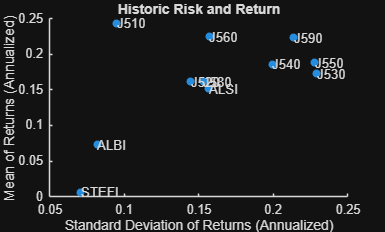

clf; %clear figure
% portfolioexamples_plot('Historic Risk and Return', ...
%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});
scatter(12*q.AssetMean,sqrt(12*diag(q.AssetCovar)),'Filled');
text(12*q.AssetMean,sqrt(12*diag(q.AssetCovar)),q.AssetList);
title('Historic Risk and Return');
xlabel('Standard Deviation of Returns (Annualized)');
ylabel('Mean of Returns (Annualized)');

#### Portfolio weights for 2 Assets

Tickers to be considered 

tickers = {'J510','J550'};

Calculating the Risk-Return trade-off for two-risky assets

Create a new Portfolio objects that incorporates the specified tickers only and estimate the asset moments.

p = Portfolio('AssetList',allDataTable.Properties.VariableNames(tickers));
Returns2 = allDataReturnsTable{:,tickers};
p = estimateAssetMoments(p,Returns2);

Number of rows of weights

rowNum = 60;

Generate a weight vector for 2 assets (with size 61 x 2)

Wts = (0:rowNum)/rowNum;
PortWts = [Wts',(1-Wts)'];

#### Risk-Return relationship for 2 Assets

Compute return and risk for each weight vector (How are the returns calculated?) 

ret = estimatePortReturn(p, PortWts')

ret =     0.0190
    0.0188
    0.0186
    0.0184
    0.0183
    0.0181
    0.0179
    0.0177
    0.0175
    0.0173
    0.0171
    0.0170
    0.0168
    0.0166
    0.0164


rsk = estimatePortRisk(p,PortWts')

rsk =     0.0542
    0.0536
    0.0531
    0.0525
    0.0520
    0.0516
    0.0511
    0.0507
    0.0503
    0.0500
    0.0496
    0.0493
    0.0491
    0.0488
    0.0486


We can demonstrate how this is computed

mu = mean(Returns2); 
Sigma = cov(Returns2);

The portfolio return: $R_p= \omega'\mu$

PortWts(1,:) * mu'

ans = 0.0190

The portfolio risk: $\sigma_p = \omega'\Sigma \omega$

sqrt(PortWts(1,:) * Sigma * PortWts(1,:)') 

ans = 0.0542

To vectorise and compute the entire vector of returns

PortWts * mu'

ans =     0.0190
    0.0188
    0.0186
    0.0184
    0.0183
    0.0181
    0.0179
    0.0177
    0.0175
    0.0173
    0.0171
    0.0170
    0.0168
    0.0166
    0.0164


sqrt(diag(PortWts * Sigma * PortWts'))

ans =     0.0542
    0.0536
    0.0531
    0.0525
    0.0520
    0.0516
    0.0511
    0.0507
    0.0503
    0.0500
    0.0496
    0.0493
    0.0491
    0.0488
    0.0486


#### Add an Efficient Frontier

Add risk return curves to plot 

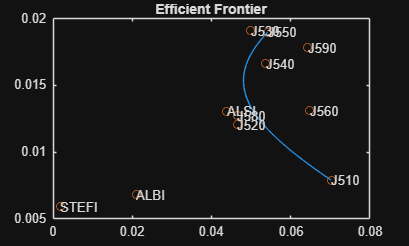

clf;
plot(rsk, ret);
title('Efficient Frontier');
hold on;
scatter(sqrt(diag(q.AssetCovar)), q.AssetMean);
text(sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList);
hold on;

#### Visualise the weights 

Plot the control simplex as an inset plot 

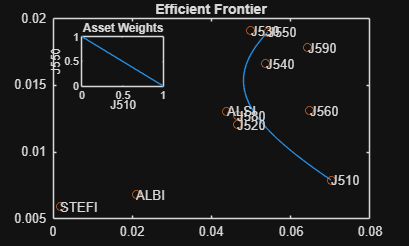

%portfolioexamples_plot('Historic Risk and Return', ...
%	{'line', rsk, ret}, ...
%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});


axes('Position',[.2 .65 .2 .2])
box on

plot(PortWts(:,1),PortWts(:,2));
% plot(PortWts)
title('Asset Weights')
xlabel('J510')
ylabel('J550')
hold off

#### The effect of correlations

Calculating the Risk-Return trade-off for two-risky assets

% With different correlation
rho2ij = [1,0.5,0,-0.5,-0.97];
% We use the original standard deviations
s1ij = sqrt(diag(p.AssetCovar));

Compute the portfolio volatility

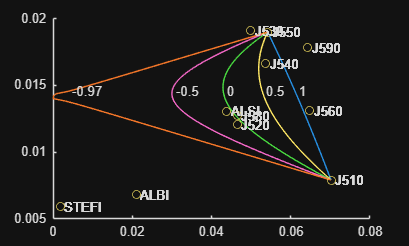

%loop over different correlations
figure; hold on;
for j = 1:length(rho2ij)
    %create the family of correlation matrices
    Rho2 = eye(2); %initialise correlations
    Rho2(2,1) = rho2ij(j);
    Rho2(1,2) = Rho2(2,1);%symmetric
    Sigma2 = s1ij .* Rho2 .* s1ij;
    % Compute return and risk
    ret = PortWts * p.AssetMean;
    rsk = sqrt(diag(PortWts * Sigma2 * PortWts'));
    % Matrix to plot (plot without portfolio object)
    %portfolioexamples_plot('Historic Risk and Return', ...
	%    {'line', rsk, ret,{string(rho2ij(j))}}, ...
	%    {'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'}); 
    plot(rsk, ret);
    scatter(sqrt(diag(q.AssetCovar)), q.AssetMean);
    text(sqrt(diag(q.AssetCovar))+0.001, q.AssetMean, q.AssetList);
    text(rsk(25)+0.001,ret(25),{string(rho2ij(j))})
end

#### Fully invested portfolio with varying risk aversion 

Plot Efficient frontier by varying risk aversion by solving the risk adjusted return maximisation:


$$\max_{\omega} \left\{ {\mu \omega - \frac{\gamma}{2} \omega \Sigma \omega} \right\} s.t. \omega' {\bf 1} = 1$$


for the vector of portfolio weights $\omega$ where these sum to one. This is done by instead solving: 


$$\min_x \left\{ {\frac{1}{2} x' H x + f'x } \right\} s.t. A x \leq b$$


for an appropriate choice of H, f, A and x. Where we implement the equality constraint as two inequality constraints or use the equality constraint functionality. Here $H \rightarrow \Sigma$ and $f \rightarrow -\mu$ with the correct constraint convention. 

% Create the range of risk aversion parameters
lambda = linspace(-0.25,0.25,45);
% Fully Invested
q.AEquality = ones(1,length(q.AssetMean));
q.bEquality = 1;

Initialise the weights

PortWts = NaN(length(lambda),length(q.AssetMean));

Find the weight vector for each return level using that $H = \Sigma$ (the asset covariance matrix) and that $f = - \lambda \mu $ for the asset returns $\mu$ and the parameter $\lambda$ that selects the return level at which the risk is minimised. 

for i = 1:length(lambda)
    f = - lambda(i) * q.AssetMean; % This moves the solution up along the efficient frontier
    H = q.AssetCovar; %the covariance matrix
    PortWts(i,:) = quadprog(H,f,[],[],q.AEquality,q.bEquality) ;
end


Minimum found that satisfies the constraints.

Optimization completed because the objective function is non-decreasing in 
feasible directions, to within the value of the optimality tolerance,
and constraints are satisfied to within the value of the constraint tolerance.

<stopping criteria details>

Minimum found that satisfies the constraints.

Optimization completed because

#### Compute Portfolio Risk and Return

Compute return and risk for each weight vector

ret = estimatePortReturn(q, PortWts');
rsk = estimatePortRisk(q,PortWts');

Add risk return curves to plot

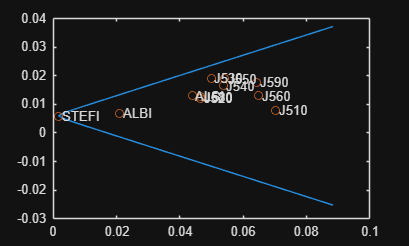

clf;
%portfolioexamples_plot('Historic Risk and Return', ...
%	{'line', rsk, ret}, ...
%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});
plot(rsk, ret); hold on;
scatter(sqrt(diag(q.AssetCovar)), q.AssetMean);
text(sqrt(diag(q.AssetCovar))+0.001, q.AssetMean, q.AssetList);

#### Exclude the Cash and Market Indices

tickers = setdiff(allDataTable.Properties.VariableNames,{'STEFI','ALSI'})

tickers = 1×9 cell array
    {'ALBI'}    {'J510'}    {'J520'}    {'J530'}    {'J540'}    {'J550'}    {'J560'}    {'J580'}    {'J590'}


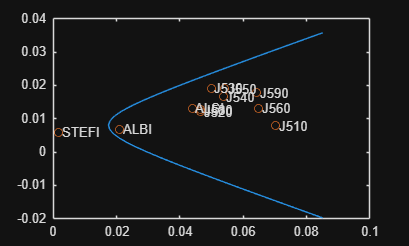

Returns = allDataReturnsTable{:,tickers};
mu = mean(Returns);
Sigma = cov(Returns);
% Create the range of risk aversion parameters
lambda = linspace(-0.25,0.25,45);
% Fully Invested
Aeq = ones(1,length(mu));
beq = 1;
% initialise the weights
PortWts = NaN(length(lambda),length(mu));
% set the QP options
optionsQP = optimset('quadprog')';
optionsQP= optimset(optionsQP,'Display','off');
% generate the efficient frontier
for i = 1:length(lambda)
    f = - lambda(i) * mu; % This moves the solution up along the efficient frontier
    H = Sigma; %the covariance matrix
    [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,f,[],[],Aeq,beq,[],[],[],optionsQP);
end
% compute risk and return 
ret0 = PortWts * mu';
rsk0 = sqrt(diag(PortWts * Sigma * PortWts'));
% plot
clf;
plot(rsk0, ret0); hold on;
scatter(sqrt(diag(q.AssetCovar)), q.AssetMean);
text(sqrt(diag(q.AssetCovar))+0.001, q.AssetMean, q.AssetList);

%portfolioexamples_plot('Historic Risk and Return', ...
%	{'line', rsk0, ret0}, ...
%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});


#### Include the no short selling constraint (as an inequality constraint)

We again want to solve an optimisation the maximises the risk adjusted returns. However, now we need to include both the full investment constraint: $\sum_i \omega_i = 1$(wihich in vector notation is $\omega' {\bf 1} =1 $and is an equality constraint), and the inequality constraints $\omega_i \geq 0$ (or in vector notation $\omega \geq 0$). We need to solve the following quadratic problem

$\max_{\omega} \left\{ {\mu \omega - \frac{\gamma}{2} \omega \Sigma \omega} \right\} s.t. \omega' {\bf 1} = 1 \mbox{ and } \omega \geq 0$.

We can set up the range of the hyper-parameter that controls the risk aversion

% Create the range of risk aversion parameters
lambda = 12*linspace(-1,1,45);

The full investment constraints 

% Fully Invested (equality constraint)
Aeq = ones(1,length(mu));
beq = 1;

We implement no short-selling (using that $A x \leq b$). We have that A = - I for the identity marix I, and b = 0.

% No Short-selling (inequality constraint)
A = -eye(length(mu));
b = zeros(length(mu),1);

Initialise the weights

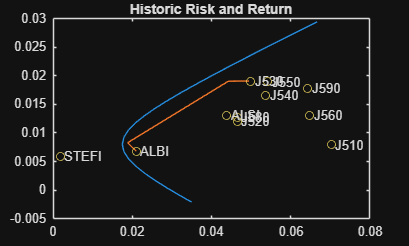

% initialise the weights
PortWts = NaN(length(lambda),length(mu));
% set the QP options
optionsQP = optimset('quadprog')';
optionsQP= optimset(optionsQP,'Display','off');
% generate the efficient frontier
for i = 1:length(lambda)
    f = - lambda(i) * mu; % This moves the solution up along the efficient frontier
    H = Sigma; %the covariance matrix
    [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,f,A,b,Aeq,beq,[],[],[],optionsQP);
end
% compute risk and return 
ret1 = PortWts * mu';
rsk1 = sqrt(diag(PortWts * Sigma * PortWts'));
% plot
clf;
%portfolioexamples_plot('Historic Risk and Return', ...
%    {'line', rsk0(15:end-5), ret0(15:end-5)}, ...
%	{'line', rsk1, ret1}, ...
%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});
plot(rsk0(15:end-5), ret0(15:end-5)); 
title('Historic Risk and Return'); hold on;
plot(rsk1, ret1);
scatter(sqrt(diag(q.AssetCovar)), q.AssetMean);
text(sqrt(diag(q.AssetCovar))+0.001, q.AssetMean, q.AssetList);

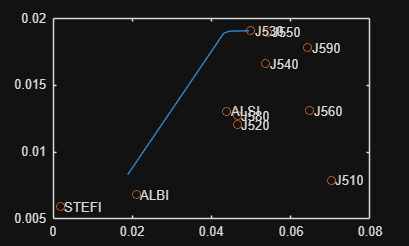

% Create the range of risk aversion parameters
lambda = 12*linspace(0,1,45);
% No Short-selling (upper and lower bounds)
ub = ones(length(mu),1);
lb = zeros(length(mu),1);
% initialise the weights
PortWts = NaN(length(lambda),length(mu));
% set the QP options
optionsQP = optimset('quadprog')';
optionsQP= optimset(optionsQP,'Display','off');
% generate the efficient frontier
for i = 1:length(lambda)
    f = - lambda(i) * mu; % This moves the solution up along the efficient frontier
    H = Sigma; %the covariance matrix
    [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,f,[],[],Aeq,beq,lb,ub,[],optionsQP);
end
% compute risk and return 
ret = PortWts * mu';
rsk = sqrt(diag(PortWts * Sigma * PortWts'));
% plot
clf;
plot(rsk, ret); hold on;
scatter(sqrt(diag(q.AssetCovar)), q.AssetMean);
text(sqrt(diag(q.AssetCovar))+0.001, q.AssetMean, q.AssetList);

%portfolioexamples_plot('Historic Risk and Return', ...
%	{'line', rsk, ret}, ...
%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### Mutual/Pension Fund Efficient Frontier (QP) return targeting

Again only consider Bonds and Equities. 

Plot efficient frontier by varying the return target directly

$\min_{\omega} \left\{ {\frac{1}{2} \omega' \Sigma \omega} \right\} s.t.~~ \omega' {\bf 1} = 1, \omega'\mu = \mu_i \mbox{ and } \omega \geq 0$.

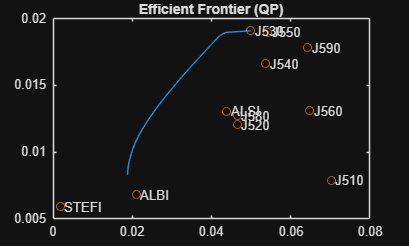

% Create the range of risk aversion parameters
% retTarget = min(mu):((max(mu)-min(mu))/90):max(mu);
retTarget = min(ret):((max(ret)-min(ret))/90):max(ret);
% No Short-selling (upper and lower bounds)
ub = ones(length(mu),1);
lb = zeros(length(mu),1);
% Equality constraint (fully invested)
Aeq = ones(1,length(mu));
beq = 1;
% Equality constraint (return target)
Aeq = [Aeq; mu];
beq = [beq; 0];
% initialise the weights
PortWts = NaN(length(retTarget),length(mu));
% set the QP options
optionsQP = optimset('quadprog')';
optionsQP= optimset(optionsQP,'Display','off');
% generate the efficient frontier
for i = 1:length(retTarget)
    beq(2) = retTarget(i); % This moves the solution up along the efficient frontier
    H = Sigma; %the covariance matrix
    [PortWts(i,:),fVal,exitFlag(i)] = quadprog(H,zeros(size(mu))',[],[],Aeq,beq,lb,ub,[],optionsQP);
end
ret = PortWts * mu';
rsk = sqrt(diag(PortWts * Sigma * PortWts'));
clf;
plot(rsk, ret); 
title('Efficient Frontier (QP)'); hold on;
scatter(sqrt(diag(q.AssetCovar)), q.AssetMean);
text(sqrt(diag(q.AssetCovar))+0.001, q.AssetMean, q.AssetList);

%portfolioexamples_plot('Efficient Frontier (QP)', ...
%	{'line', rsk, ret}, ...
%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### Add the Sharpe Ratio Maximising Portfolio (SQP)

The Sharpe ratio maximising portfolio is the solution too:

$\max_{\omega} \left\{ {\frac{(\omega'\mu - R_{\mathrm{rfr}})}{\sqrt{\omega' \Sigma \omega}}} \right\} s.t. ~~\omega' {\bf 1} = 1 \mbox{ and } \omega \geq 0$.

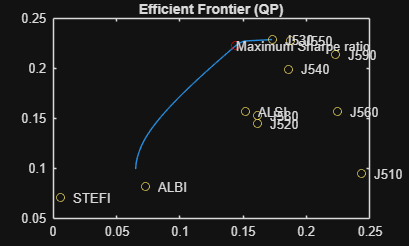

Returns = allDataReturnsTable{:,tickers};
% risk free rate
RFR = allDataReturnsTable{:,{'STEFI'}};
% monthy sampled arithmetic mean of simple returns
mu = mean(Returns);
% average risk free rate (when to use geometric average)
ERFR = mean(RFR); 
% covariance
Sigma = cov(Returns);
% Equally weighted portfolio
x0 = ones(size(mu))/length(mu);
%initialise the weights
Wts = NaN(1,length(mu));
% objective function to maximise the SR
fn0 = @(x) (-(x*mu' - ERFR)/sqrt(x*Sigma*x'));
% No Short-selling (upper and lower bounds)
ub = ones(length(mu),1);
lb = zeros(length(mu),1);
% Equality constraint (fully invested)
Aeq = ones(1,length(mu));
beq = 1;
% Use SQP to solve for the tangency portfolio
options = optimoptions(@fmincon,'Algorithm','sqp','OptimalityTolerance',1e-8,'Display','off');
x = fmincon(fn0,x0,[],[],Aeq,beq,lb,ub,[],options); 
% plot the maximum SR portfolio on EF
retSR = x*mu';
rskSR = sqrt(x*Sigma*x');
clf; 
plot(sqrt(12)*rsk, 12*ret); 
title('Efficient Frontier (QP)'); hold on;
scatter(sqrt(12)*rskSR,12*retSR,'r'); 
text(sqrt(12)*rskSR,12*retSR,'Maximum Sharpe ratio');
scatter(sqrt(12*diag(q.AssetCovar)), 12*q.AssetMean);
text(sqrt(12*diag(q.AssetCovar))+0.01, 12*q.AssetMean, q.AssetList);


%portfolioexamples_plot('Efficient Frontier (QP)', ...
%    {'line', rsk, ret}, ...
%    {'scatter',rskSR,retSR,{'Maximum Sharpe ratio'},'r'}, ...
%	{'scatter', sqrt(diag(q.AssetCovar)), q.AssetMean, q.AssetList, '.r'});

#### Fully invested, no short selling and positive risk-aversion

Plot SML (Security Market Line) 

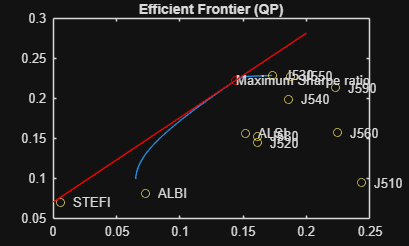

%hold on
% SML through the tangency portfolio
SML = @(x) (12*ERFR + sqrt(12)*(retSR-ERFR)/rskSR*x);
x = linspace(0,0.20,20);
% plot market line
plot(x,SML(x),'r')
% legend("Market Line")
hold off;

#### Visualise the Sharpe Ratio values 

Plot the Sharpe Ratio against risk levels

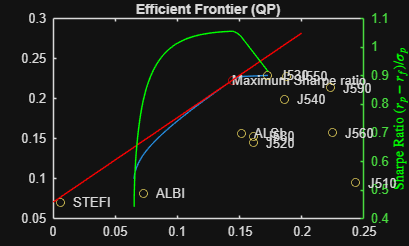

%plot the Sharpe Ratio against risk levels
yyaxis right
ylabel('Sharpe Ratio ${ ( r_p -r_{f} ) / \sigma_p }$','interpreter','latex','Color','g')
% plot the Sharpe Ratio against risk level
hold on
plot(sqrt(12)*rsk,sqrt(12)*(ret-ERFR)./rsk,'-g')
hold off